% (C) Copyright 2011-2024 DQ Robotics Developers
% 
% This file is part of DQ Robotics.
% 
%     DQ Robotics is free software: you can redistribute it and/or modify
%     it under the terms of the GNU Lesser General Public License as published by
%     the Free Software Foundation, either version 3 of the License or
%     (at your option) any later version.
% 
%     DQ Robotics is distributed in the hope that it will be useful,
%     but WITHOUT ANY WARRANTY; without even the implied warranty of
%     MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
%     GNU Lesser General Public License for more details.
% 
%     You should have received a copy of the GNU Lesser General Public License
%     along with DQ Robotics.  If not, see <http://www.gnu.org/licenses/>.
%
% DQ Robotics website: dqrobotics.github.io
%
% Contributors to this file:
%     Frederico Fernandes Afonso Silva (frederico.silva@ieee.org)
clear all; %#ok
close all;
clc

# Static world (part 1)

## Introduction

Now that we understand the basics of the CoppeliaSim, we will start to interact with scene objects through the MATLAB interface. Before we begin, however, let us add the namespace to our workspace. 

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

Please remember that MATLAB allows you to run this file section by section (Ctrl + Enter shortcut) if you want to follow this tutorial step by step.

Now, let us open the scene [static_world.ttt]. You should see something similar to the image below.

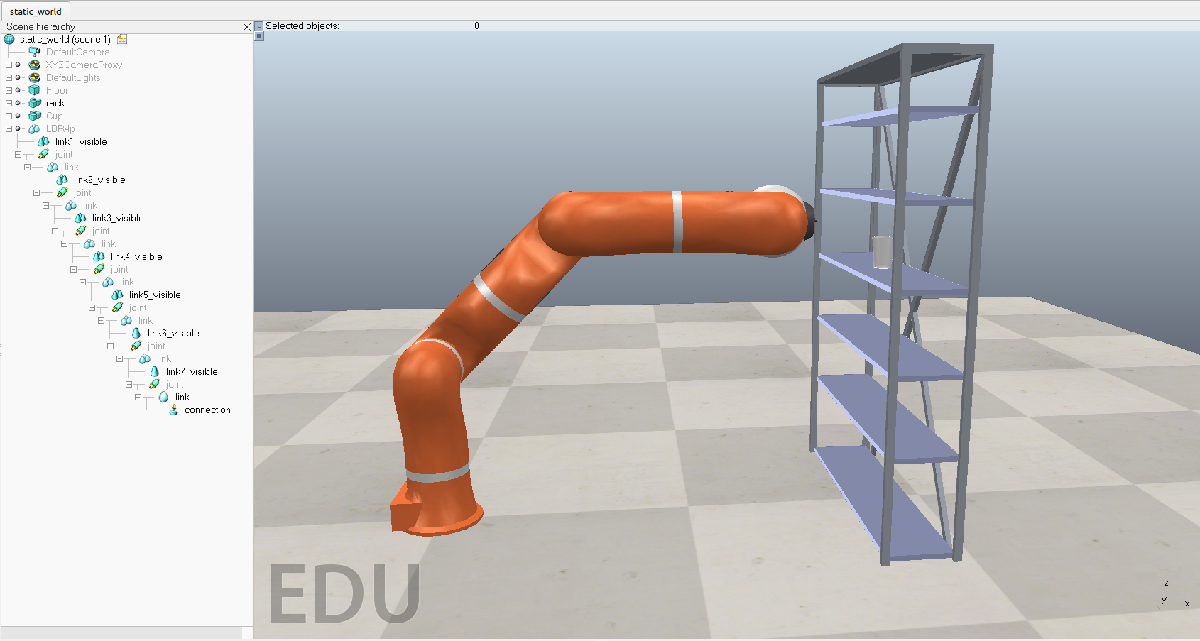

## Environment setup

You only need to set up the environment the first time you use the class 'DQ_CoppeliaSimInterfaceZMQ'. The location and extension of the necessary files depend on your operational system.

### Instructions for any operating systems

Add the ZMQ remote API, the DQ_CoppeliaSimInterface, and DQ_CoppeliaSimInterfaceZMQ folders to MATLAB's path:

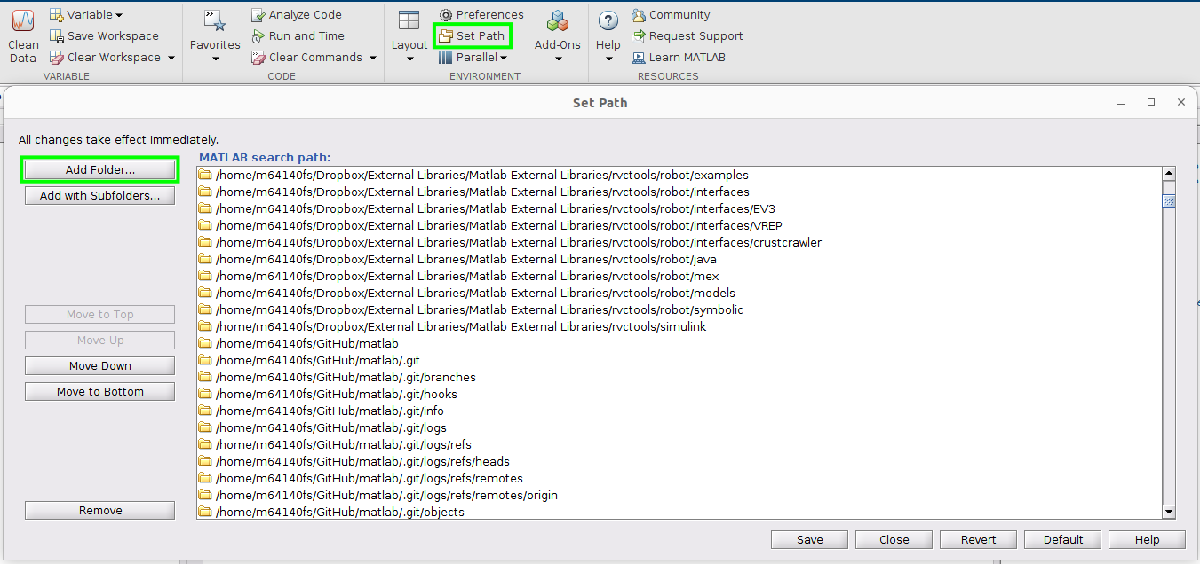

The DQ_CoppeliaSimInterface and the DQ_CoppeliaSimInterfaceZMQ are available on [DQ Robotics](https://github.com/orgs/dqrobotics/repositories). As for the ZMQ remote API folder, in CoppeliaSim v4.6.0, and likely in other versions, it can be found in:

- **Linux and Windows:** [COPPELIA_SIM_FOLDER]/programming/zmqRemoteApi/clients/matlab

- **MacOS:** [COPPELIA_SIM_FOLDER]/Contents/Resources/programming/zmqRemoteApi/clients/matlab

For MacOS, remember you must right-click 'coppeliaSim.app' and select the option 'Show Package Contents' to find the necessary folders and copy them to a more accessible location.

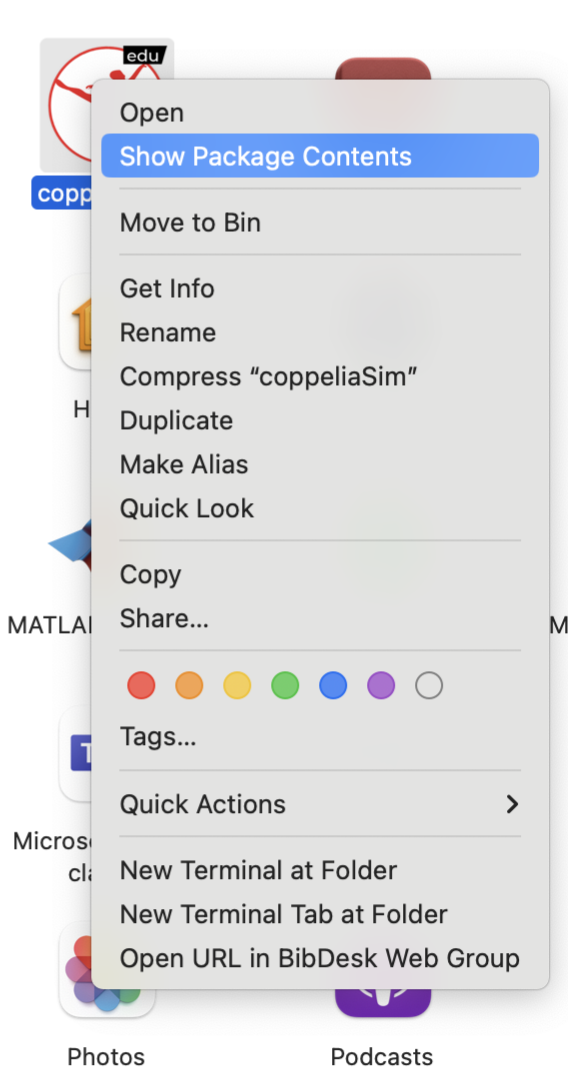

## Communicating with CoppeliaSim

Communication with CoppeliaSim is handled by the class 'DQ_CoppeliaSimInterfaceZMQ'. We establish communication by running

cs = DQ_CoppeliaSimInterfaceZMQ();

This version of DQ_CoppeliaSimInterfaceZMQ is compatible with CoppeliaSim 4.7.0-rev4


cs.connect;

Until we break the communication, CoppeliaSim is ready to receive commands from MATLAB, such as starting the simulation.

cs.start_simulation();

You should see something similar to the image below in CoppeliaSim.

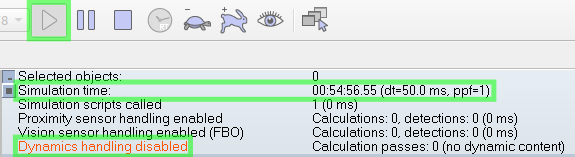

The grayed-out 'Start/resume simulation' button and the running clock indicate that the simulation is running (even if the robot/objects aren't moving yet!). Additionally, the red warning is letting us know that [the dynamics are disabled](https://manual.coppeliarobotics.com/en/simulationPropertiesDialog.htm) (it's a [static_world.ttt] after all (: ), which means CoppeliaSim is working as a visualization tool without using any of the available [physics engines](https://manual.coppeliarobotics.com/en/dynamicsModule.htm).

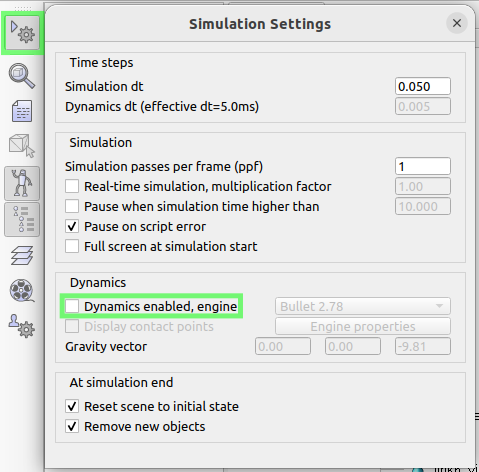

## Referring to an object in CoppeliaSim

Objects in CoppeliaSim have aliases, which you can see by selecting any of them. For instance, by selecting the cup

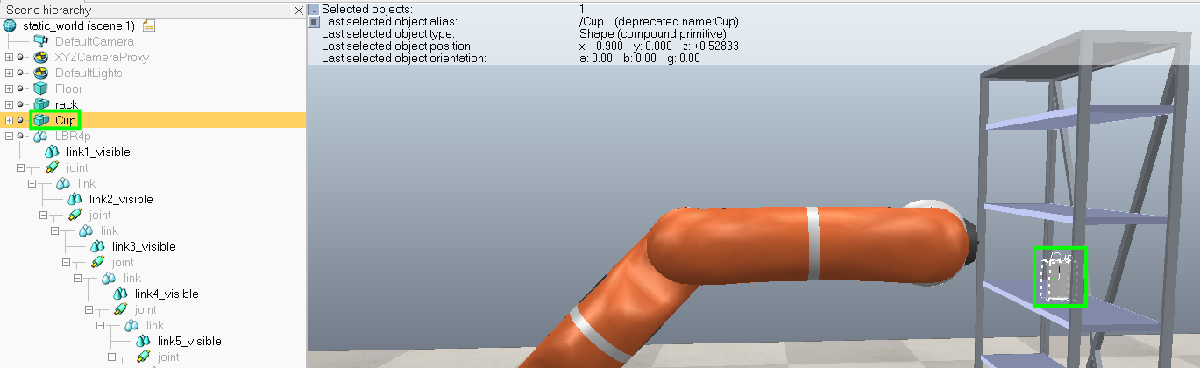

you can see in the top box ('Selected objects') that the cup's alias (name) is '/Cup'.

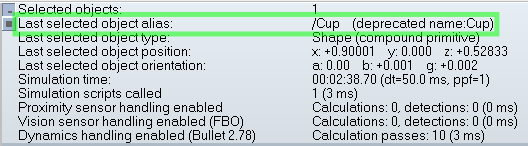

We can also refer to an object by its handle. For instance, we can get the cup's handle through its alias.

cs.get_object_handle('/Cup')

ans = 18

Most methods in the class 'DQ_CoppeliaSimInterfaceZMQ' require the object's alias to interact with it in CoppeliaSim, but the [underlying API methods](https://manual.coppeliarobotics.com/en/remoteApiFunctionsMatlab.htm) use the object's handle. The class 'DQ_CoppeliaSimInterfaceZMQ' does this conversion from alias to handle automatically for you, but it's essential to keep this in mind if you want to expand the list of currently supported methods in 'DQ_CoppeliaSimInterfaceZMQ'. You can check this list in the class documentation or, more conveniently, use the 'help/doc' MATLAB functions (you can scroll through the box below and click on the methods if you want!).

help DQ_CoppeliaSimInterfaceZMQ

  (C) Copyright 2011-2025 DQ Robotics Developers
  
  This file is part of DQ Robotics.
  
      DQ Robotics is free software: you can redistribute it and/or modify
      it under the terms of the GNU Lesser General Public License as published by
      the Free Software Foundation, either version 3 of the License, or
      (at your option) any later version.
  
      DQ Robotics is distributed in the hope that it will be useful,
      but WITHOUT ANY WARRANTY; without even the implied warranty of
      MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
      GNU Lesser General Public License for more details.
  
      You should have received a copy of the GNU Lesser General Public License
      along with DQ Robotics.  If not, see <http://www.gnu.org/licenses/>.
  
  DQ Robotics website: dqrobotics.github.io
  
  Contributors:
  
     1. Juan Jose Quiroz Omana (juanjose.quirozomana@manchester.ac.uk)
          - Responsib

You can also check the documentation of specific methods if you are still unsure what their signature is. For example, the method 'get_object_translation', which we will use in the next section, requires only the object's alias.

help cs.get_object_translation

--- help for DQ_CoppeliaSimInterfaceZMQ/get_object_translation ---

  This method returns a pure quaternion that represents the translation of an object 
  in the CoppeliaSim scene.
 
  Usage: translation = get_object_translation(objectname)
 
        objectname: The object name
        translation: The pure quaternion that represents the translation of
                     the desired object in the CoppeliaSim scene.
 
  Example:
      translation = get_object_translation('DefaultCamera');



## Reading information from CoppeliaSim

'DQ_CoppeliaSimInterfaceZMQ' allows us to get information about an object's location in the CoppeliaSim scene. For instance, we can get the cup's translation,

cs.get_object_translation('/Cup')

ans =          0.9i + 0.52833k

rotation,

cs.get_object_rotation('/Cup')

ans =          1

and pose.

cs.get_object_pose('/Cup')

ans =          (1) + E*(0.45i + 0.26416k)

All the results above were given with respect to the inertial frame.

## Sending commands to CoppeliaSim

Similarly to the menu buttons 'Object/item shift' and 'Object/item rotate', we can move objects in a CoppeliaSim scene using the 'DQ_CoppeliaSimInterfaceZMQ' class. For instance, we can move the cup to the top shelf

p = 0.900*i_ + 0.82833*k_;
cs.set_object_translation('/Cup', p);

and flip its orientation.

r = cos(pi/2) + i_*sin(pi/2);
cs.set_object_rotation('/Cup', r);

We can also take it off the shelf.

p0 = 0.4*i_ + 0.4*k_;
x0 = 1 + (1/2)*E_*p0;
cs.set_object_pose('/Cup', x0);

Notice that since the dynamics are disabled, the cup will not fall!

## Finishing communication with CoppeliaSim

Now we can finishing the simulation.

cs.stop_simulation();

# Homework

- Save the [static_world.ttt] scene as [static_world_part1_homework.ttt] and, in it, do 2-5.

- Read and store the rack's pose.

- Move the rack to position (0.900, 0.200, 0.400).

- Restore the rack to its initial pose.

- Bonus: lay the cup in the bottom shelf.